clear all; close all; clc;

The following steps here can be used to implement CFAR in the next MATLAB exercise. You can use the code template below to get started as well.

**T** : Number of Training Cells

**G** : Number of Guard Cells

**N** : Total number of Cells

- Define the number of training cells and guard cells

- Start sliding the window one cell at a time across the complete FFT 1D array. Total window size should be: 2(T+G)+CUT

- For each step, sum the signal (noise) within all the leading or lagging training cells

- Average the sum to determine the noise threshold

- Using an appropriate offset value scale the threshold

- Now, measure the signal in the CUT, which is T+G+1 from the window starting point

- Compare the signal measured in 5 against the threshold measured in 4

- If the level of signal measured in CUT is smaller than the threshold measured, then assign 0 value to the signal within CUT.

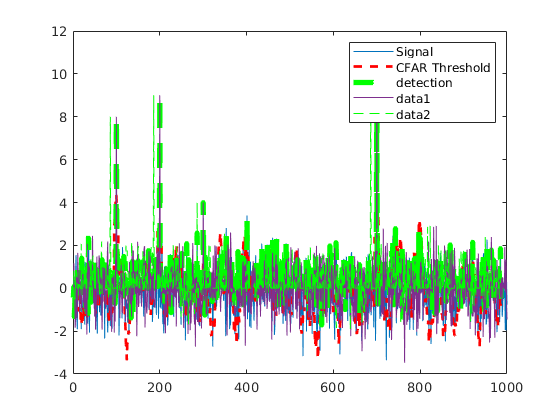

% Implement 1D CFAR using lagging cells on the given noise and target scenario.

% Data_points
Ns = 1000;

% Generate random noise
s=randn(Ns,1);


%Targets location. Assigning bin 100, 200, 300 and 700 as Targets with the amplitudes of 8, 9, 4, 11.
s([100 ,200, 300, 700])=[8 9 4 11];

%plot the output
plot(s);

% TODO: Apply CFAR to detect the targets by filtering the noise.

% 1. Define the following:
% 1a. Training Cells
% 1b. Guard Cells 
G = 4;               %Guard cells
T = 10;              %Training cells

% Offset : Adding room above noise threshold for desired SNR 
offset=3;

% Vector to hold threshold values 
threshold_cfar = [];

%Vector to hold final signal after thresholding
signal_cfar = [];

% 2. Slide window across the signal length
for i = 1:(Ns-(G+T))     
    
    % 2. - 5. Determine the noise threshold by measuring it within the training cells
    noise_level = sum(s(i:i+T-1));

    % 6. Measuring the signal within the CUT
    threshold = (noise_level/T)*offset;
    threshold_cfar = [threshold_cfar, {threshold}];
    % 8. Filter the signal above the threshold

    signal = s(i+T+G);
    
    if(signal<threshold)
        signal = 0;

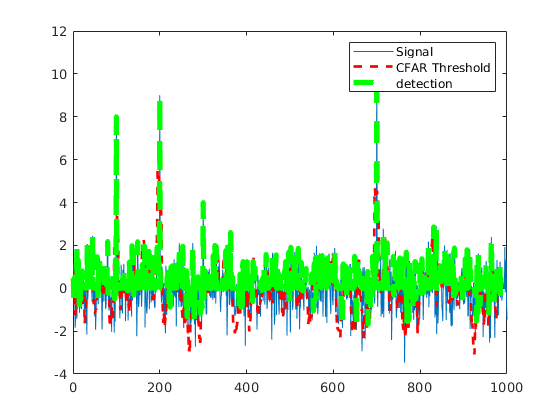

    end
    
    signal_cfar = [signal_cfar, {signal}];
end

% plot the filtered signal

plot (cell2mat(signal_cfar),'g--');

% plot original sig, threshold and filtered signal within the same figure.
figure,plot(s);
hold on,plot(cell2mat(circshift(threshold_cfar,G)),'r--','LineWidth',2)
hold on, plot (cell2mat(circshift(signal_cfar,(T+G))),'g--','LineWidth',4);
legend('Signal','CFAR Threshold','detection')